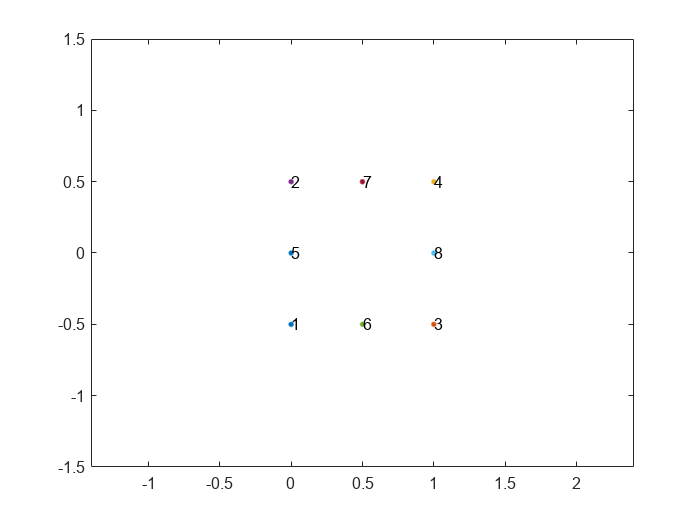

[Nnode, Nelement, Coordinate, Ielement, dL, dW] = read_mesh_info();

num = 1:Nelement; % 绘制的单元编号
% num = 1:2; % 绘制的单元编号
t = 0.02; % 动画时间

for i = 1:length(num)
	draw(num(i),t,Ielement,Coordinate,dL,dW)
end

xlim([min(Coordinate(Ielement(num,:),1))-dL,...
	max(Coordinate(Ielement(num,:),1))+dL]);
ylim([min(Coordinate(Ielement(num,:),2))-dW,...
	max(Coordinate(Ielement(num,:),2))+dW]);
axis equal

function draw(num,t,Ielement,Coordinate,dL,dW)
% global Ielement Coordinate
ele1 = Ielement(num,:);
for i = 1:length(ele1)
	plot(Coordinate(ele1(i),1),Coordinate(ele1(i),2),'.','MarkerSize',10)
	xlim([min(Coordinate(ele1(:),1))-dL,max(Coordinate(ele1(:),1))+dL])
	ylim([min(Coordinate(ele1(:),2))-dW,max(Coordinate(ele1(:),2))+dW])
	text(Coordinate(ele1(i),1),Coordinate(ele1(i),2),num2str(ele1(i)))
	hold on
	pause(t)
end
end
